# Parallel Reactions in a PFR with Heat Effects

The case study in this MATLAB Live Script is adapted from Example 12-5 from Essentials of Chemical Reaction Engineering 2nd Edition by H. Scott Fogler. This case study models the behavior of parallel reactions in a nonisothermal plug flow reactor (PFR). 

Code authors: Austin Johns and Dr. Ashlee N. Ford Versypt, ashleefv@buffalo.edu

## Learning Objectives

After completing this lesson, students should be able to 

- write a MATLAB function to define a system of ODEs

- use **ode45** to solve a system of ODEs

- create plots using MATLAB

- model parallel reactions in a PFR with heat effects

## Problem Statement

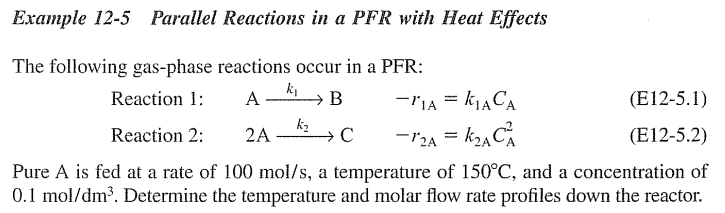

#### Part a

Solve Example 12-5 assuming the feed is kept at a constant temperature. This part is done for you.


$$\frac{dT}{dV}=0$$


#### Part b

Solve Example 12-5 assuming the feed temperature is unregulated.


$$\frac{dT}{dV}=\frac{(-r_{1A})(\Delta H_{Rx1A})\;+\;(-r_{2A})(\Delta H_{Rx2A})}{F_A C_{P_A}\;+\;F_B C_{P_B}\;+\;F_C C_{P_C}}$$


#### Part c

Solve Example 12-5 including both heat exchange terms and reaction heat terms.


$$\frac{dT}{dV}=\frac{U_a(T_a-T)\;+\;(-r_{1A})(\Delta H_{Rx1A})\;+\;(-r_{2A})(\Delta H_{Rx2A})}{F_A C_{P_A}\;+\;F_B C_{P_B}\;+\;F_C C_{P_C}}$$


### Default parameters and additional information


$$C_{A_0} = C_{T_0} = 0.1\;\frac{\text{mol}}{\text{dm}^3}$$



$$T_0 = 150\;^{\circ}\text{C}$$



$$\Delta H_{Rx1A} = 20,000 \;\text{J/(mol of A reacted in reaction 1)}$$



$$\Delta H_{Rx2A} = -60,000 \;\text{J/(mol of A reacted in reaction 2)}$$



$$C_{P_A} = 90 \; \text{J/mol}^{\circ}\text{C}$$



$$C_{P_B} = 90 \; \text{J/mol}^{\circ}\text{C}$$



$$C_{P_C} = 180 \; \text{J/mol}^{\circ}\text{C}$$



$$U_a = 4000 \; \text{J/dm}^3\text{s}^{\circ}\text{C}$$



$$T_a = 100\;^{\circ}\text{C (Constant)}$$



$$\frac{E_1}{R} = 4000 \; \text{K}$$



$$\frac{E_2}{R} = 9000 \; \text{K}$$


### Explicit equations for the two rate constants


$$k_{1A} = 10\exp\left[\frac{E_1}{R}\left(\frac{1}{300}-\frac{1}{T}\right)\right]\text{s}^{-1}$$



$$k_{2A} = 0.09\exp\left[\frac{E_2}{R}\left(\frac{1}{300}-\frac{1}{T}\right)\right]\frac{\text{dm}^3}{\text{mol s}}$$


### Explicit equations related to the stoichiometry of the gas phase, $\Delta P=0$


$$F_T = F_A + F_B + F_C$$



$$C_A = C_{T_0}\left(\frac{F_A}{F_T}\right)\left(\frac{T_0}{T}\right)$$



$$C_B = C_{T_0}\left(\frac{F_B}{F_T}\right)\left(\frac{T_0}{T}\right)$$



$$C_C = C_{T_0}\left(\frac{F_C}{F_T}\right)\left(\frac{T_0}{T}\right)$$


### Rate laws


$$r_{1A}=-k_{1A}C_A$$



$$r_{2A}=-k_{2A}C_A^2$$


### Relative rates for each reaction


$$\frac{r_{1A}}{-1} = \frac{r_{1B}}{1}; \quad r_{1B} = -r_{1A} = k_{1A}C_A$$



$$\frac{r_{2A}}{-2} = \frac{r_{2B}}{1}; \quad r_{2C} = -\frac{1}{2}r_{2A} = \frac{k_{2A}}{2}C_A^2$$


### Net rates for each species


$$r_A = r_{1A} + r_{2A} = -k_{1A}C_A-k_{2A}C_A^2$$



$$r_B = r_{1B} = k_{1A}C_A$$



$$r_C = r_{2C} = \frac{1}{2}k_{2A}C_A^2$$


### Mole Balances


$$\frac{dF_A}{dV}=r_A$$



$$\frac{dF_B}{dV}=r_B$$



$$\frac{dF_C}{dV}=r_C$$


### PFR Energy Balance

Part a: $\frac{dT}{dV}=0$

Part b: $\frac{dT}{dV}=\frac{U_a(T_a-T)\;+\;(-r_{1A})(\Delta H_{Rx1A})\;+\;(-r_{2A})(\Delta H_{Rx2A})}{F_A C_{P_A}\;+\;F_B C_{P_B}\;+\;F_C C_{P_C}}$

Part c: $\frac{dT}{dV}=\frac{U_a(T_a-T)\;+\;(-r_{1A})(\Delta H_{Rx1A})\;+\;(-r_{2A})(\Delta H_{Rx2A})}{F_A C_{P_A}\;+\;F_B C_{P_B}\;+\;F_C C_{P_C}}$

## Initial Values

Input the range of volume the ODEs will be evaluated across.

clear all % clears all existing variables from memory
clc % clears the command window
Vmin = 0; 
Vmax = 1; % dm^3
Vspan = [Vmin, Vmax]; % dm^3

Input the initial values for the dependent variables (molar flow rates and temperature) and consolidate them into one vector.

F_A0 = 100; % mol/s
F_B0 = 0; % mol/s
F_C0 = 0; % mol/s
T0 = 150+273; % deg_K
initial_values = [F_A0, F_B0, F_C0, T0]; % Consolidate initial conditions into a vector

## Solve ODEs

Solve the system of ODEs contained in the **ODEs** function below. Note that when writing this code the call for the ODE solver (the line that includes **ode45**) must go before the ODE function. In fact, the ODE function needs to be placed at the end of the code.

solution_output = ode45(@(t,y) ODEs(t,y), Vspan, initial_values);

**ode45** performs well with most ODE problems and should generally be your first choice of solver. See this webpage for more MATLAB ODE solvers and their uses: [https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

### Extract individual solutions from output

num = 101;
V_eval = linspace(Vmin,Vmax,num);  % set 101 values on the x-axis for evaluating the solution and plotting the results
y = deval(solution_output,V_eval);
F_A_soln = y(1,:);
F_B_soln = y(2,:);
F_C_soln = y(3,:);
T_soln = y(4,:);

## Plot Solution

Plot the temperature and molar flow rate profiles down the reactor.

Using the default parameter values and the PFR energy balance from Part c, the plots should resemble the following Polymath plots.

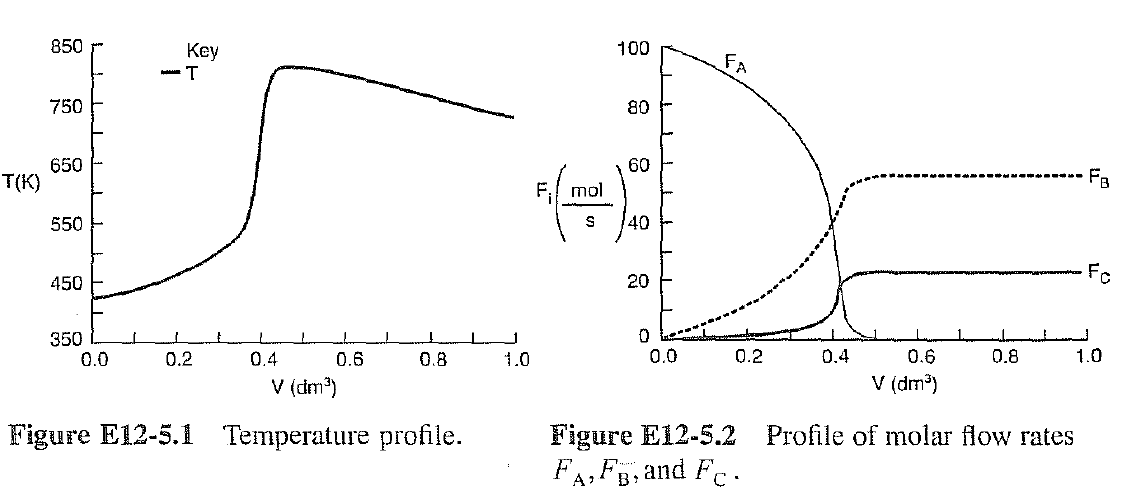

Note that we have different line styles and colors in the plots. The general plot formatting options are 

- Colors: black 'k', green 'g', red 'r', blue 'b', magenta 'm',  cyan blue 'c', yellow 'y'.

- Line types: '-' solid line, '--' dashed line, '-.' dash-dot line, ':' dotted line.

- Colors and line styles can be combined as 'r:' or 'k-.' for a red dotted line or a black dash-dot line.

- See this webpage for more details: [https://www.mathworks.com/help/matlab/ref/plot.html](https://www.mathworks.com/help/matlab/ref/plot.html) 

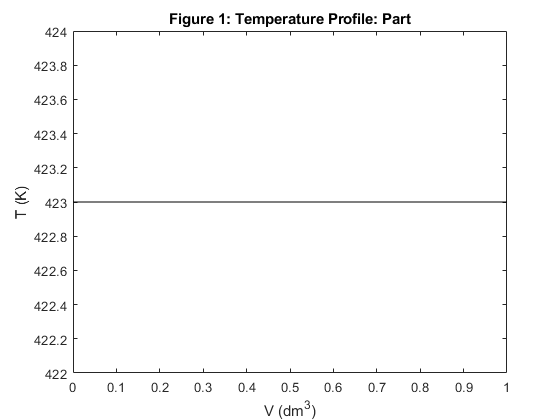

figure(1) % Plot T vs. V graph
    plot(V_eval, T_soln,'k-')
    title("Figure 1: Temperature Profile: Part")
    xlabel('V (dm^3)')
    ylabel('T (K)')

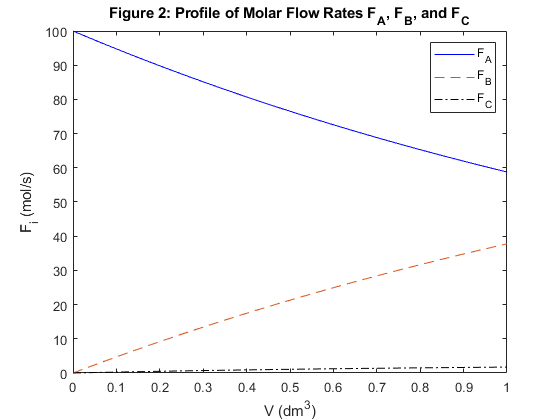

figure(2) %Plot (F_A, F_B, F_C) vs. V graph
    plot(V_eval, F_A_soln,'b-')
    hold on
    plot(V_eval, F_B_soln, '--')
    plot(V_eval, F_C_soln, 'k-.')
    hold off
    title("Figure 2: Profile of Molar Flow Rates F_A, F_B, and F_C")
    xlabel('V (dm^3)')
    ylabel('F_i (mol/s)')
    legend('F_A', 'F_B', 'F_C')

## ODEs Function

Define the system of ODEs within a MATLAB function. This will allow us to use ode45 to solve this system of ODEs. 

function dy_dV = ODEs(V, y, Part)
    % V is the x-axis, independent variable
    % y is the y-axis, set of dependent variables

    % Extract the molar flow rates and temperature from the y vector passed into the function
    F_A = y(1); % mol/s
    F_B = y(2); % mol/s
    F_C = y(3); % mol/s
    T  = y(4); % deg_K

    % Default Parameters
    C_T0 = 0.1; % mol/dm^3
    T_0 = 150 + 273; % deg_K
    
    % Additional information
    delta_H_Rx1A = -20000; % J/(mol of A reacted in reaction 1)
    delta_H_Rx2A = -60000; % J/(mol of B reacted in reaction 2)
    
    C_P_A = 90; % J/mol*deg_C
    C_P_B = 90; % J/mol*deg_C
    C_P_C = 180; % J/mol*deg_C
    U_a = 4000; % J/dm^3*s*deg_C
    T_a = 100 + 273; % deg_K (Constant) from deg_C
    
    E_1overR = 4000; %K
    E_2overR = 9000; %K

    % Explicit equations for the two rate constants
    k_1A = 10*exp((E_1overR)*((1/300)-(1/T)));  % 1/s
    k_2A = 0.09*exp((E_2overR)*((1/300)-(1/T))); % dm^3/mol*s 
    
    % Explicit equations related to the stoichiometry of the gas phase, (change in Pressure is zero)
    F_T = F_A + F_B + F_C; % Total molar flow rate in mol/s
    C_A = C_T0*(F_A/F_T)*(T_0/T); % mol/dm^3
    C_B = C_T0*(F_B/F_T)*(T_0/T); % Not used
    C_C = C_T0*(F_C/F_T)*(T_0/T); % Not used

    % Rate laws
    r_1A = -k_1A*C_A;
    r_2A = -k_2A*(C_A^2);

    % Relative rates for each reaction 
    r_1B = -r_1A; % Reaction 1
    r_2C = -0.5*r_2A; % Reaction 2
    
    % Net rates for each species
    r_A = r_1A + r_2A;
    r_B = r_1B;
    r_C = r_2C;

    % Mole balances
    dF_A_dV = r_A;
    dF_B_dV = r_B;
    dF_C_dV = r_C;

    % PFR Energy Balance
    dT_dV = 0;

    % Consolidate function output into a single vector and close the function
    dy_dV = [dF_A_dV; dF_B_dV; dF_C_dV; dT_dV];
end

## Reflection Questions

- Why are two plots helpful for displaying the results?

- Did you use one function for all three parts? If not, try using an if statement in the function to allow you to use a single function with an additional parameter to specify the part being solved. 

- Do the plots match the expected behavior of a PFR?

- Did you perform a dimensional analysis to ensure the given parameters' units and the solution's units match?

- Reduce the value of num in V_eval. Note that it must be an integer value. At approximately what value of num do the plots start to no longer look smooth (straight lines are drawn connecting adjacent evaluation points)?

- Explore changing line styles and colors. Are any of the options more visually appealing to you?

- For further exploration, see the materials from the textbook author's website: [http://websites.umich.edu/~elements/5e/12chap/live.html](http://websites.umich.edu/~elements/5e/12chap/live.html)